#  Defining the Objective Function

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code initializes the optimization problem and defines the optimization variables.

prob = optimproblem("Description","Factory Location");
x = optimvar("x");
y = optimvar("y");
X = [5 40 70];
Y = [20 50 15];

## Task 1

The x- and y-coordinates of the three stores have been stored in vectors `X` and `Y` for you.

The distance between the factory and the three stores is calculated using the following equation:

d=√(x−X)^2+(y−Y)^2

Where 

x and  y are your symbolic optimization variables, and X and Y are the coordinates of the stores.

 Performing MATLAB operations on your optimization variables will create an optimization expression.

Task

Create an optimization expression for the distance between the factory location (`x`,`y`) and the location of each of the stores (`X`,`Y`). Make sure to use element-wise exponentiation (`.^`) when squaring the differences between the x- and y-coordinates and store the result in a variable `d`.

d=sqrt((x-X).^2+(y-Y).^2)

d =   1×3 Nonlinear OptimizationExpression array with properties:

    IndexNames: {{}  {}}
     Variables: [1×1 struct] containing 2 OptimizationVariables

  See expression formulation with show.


## Task 2

Variable `d` is a 1-by-3 optimization expression array. Each element represents the distance to one of the three stores.

Task

Use `d` to create an optimization expression that represents the total distance between the factory and the three stores. Name the new optimization  expression `dTotal`.

dTotal=sum(d)

dTotal =   Nonlinear OptimizationExpression

    sum(sqrt(((x - extraParams{1}).^2 + (y - extraParams{2}).^2)))

  extraParams


## Task 3

Note that any variables that are passed to the  objective function that are not symbolic optimization variables, like  the store position vectors, will be displayed as `ExtraParams` in the output pane.

You can store optimization expressions in the `Objective` field of your optimization problem using dot notation.

`prob.Objective` `=` `expression`

Task

Store the total shipping distance `dTotal` in the `Objective` field of the optimization problem `prob`. 

prob.Objective=dTotal

prob =   OptimizationProblem with properties:

       Description: 'Factory Location'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.


## Task 4

Use the `show` function to display the current optimization problem.

show(prob)


  OptimizationProblem : Factory Location

	Solve for:
       x, y

	minimize :
       sum(sqrt(((x - extraParams{1}).^2 + (y - extraParams{2}).^2)))

       extraParams





## Further Practice

Notice that the `Description`, `ObjectiveSense`,  `Variables`, and `Objective` fields are all filled in your optimization problem. There is only one thing left to do: solve the problem!

   When your optimization problem consists of only one or two variables, it can be useful to visualize the objective function to get a sense of  where the solution is located.

This code creates a  two-dimensional contour map of the objective function where the color  corresponds to the total shipping distance. Try copy and pasting it into the Further Practice section. 

`xvec` `=` `linspace``(``0``,``75``)``;`

`yvec` `=` `linspace``(``0``,``75``)``;`

`[``x``,``y``]` `=` `meshgrid``(``xvec``,``yvec``)``;`

`distance` `=` `sqrt``((``x``-``X``(``1``))``.^``2` `+` `(``y``-``Y``(``1``))``.^``2``)``+``...`

    `sqrt``((``x``-``X``(``2``))``.^``2` `+` `(``y``-``Y``(``2``))``.^``2``)``+``...`

    `sqrt``((``x``-``X``(``3``))``.^``2` `+` `(``y``-``Y``(``3``))``.^``2``)``;`

`contourf``(``x``,``y``,``distance``)`

`ylabel``(``"Y-Coordinate"``)`

`xlabel``(``"X-Coordinate"``)`

`colorbar`

 Once you have pasted the code, click "Run Section" to visualize the objective function.

Try adding the store locations (`X`,`Y`) to the plot before moving on. 

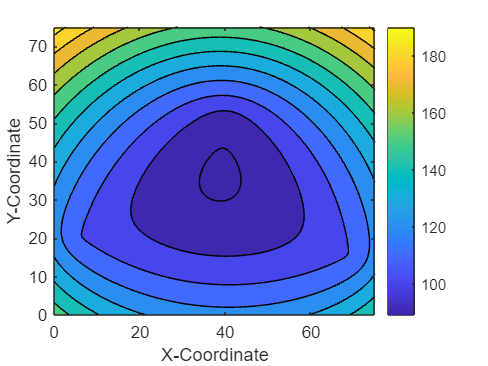

xvec = linspace(0,75);
yvec = linspace(0,75);
[x,y] = meshgrid(xvec,yvec);
distance = sqrt((x-X(1)).^2 + (y-Y(1)).^2)+...
    sqrt((x-X(2)).^2 + (y-Y(2)).^2)+...
    sqrt((x-X(3)).^2 + (y-Y(3)).^2);
contourf(x,y,distance)
ylabel("Y-Coordinate")
xlabel("X-Coordinate")
colorbar